# Notebook 02: Preprocessing and Feature Extraction

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 02**. Before running this notebook, you should have run Notebook 01 to get an understanding of the data you will be working with.

## Instructions

- Run each cell in order.

- Modify the lines that have green comments.

- This notebook, by default, assumes that time/samples are rows and channels are columns.

- Feel free to try more involved preprocessing steps, but assign your results back to the appropriate variables.

### Step 1: Ensure you are in the correct directory

clc;
clear;
cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Procedure 1: Preprocessing

### Step 1: Load the dataset

clearvars
load("datasets\training_dataset.mat")

### Step 2: Visualize the raw data

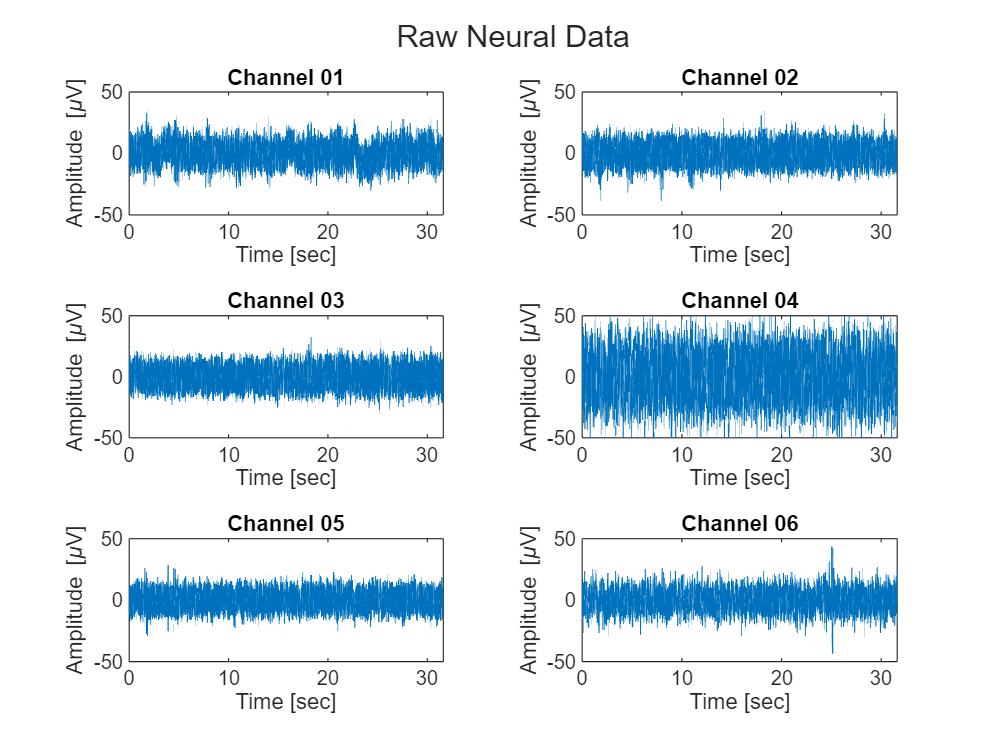

fig_1 = plot_raw_data(training_data);

### Step 3: Filter the data

#### A. Provide information for designing the filter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 750; % Change this random value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut-off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed. Alternatively, you can use MATLAB's [`filter()`](https://www.mathworks.com/help/matlab/ref/filter.html) function.

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = FilterX(b, a, training_data.raw_neural_data, ch_init_conds);

#### Step 4: Visualize the filtered data

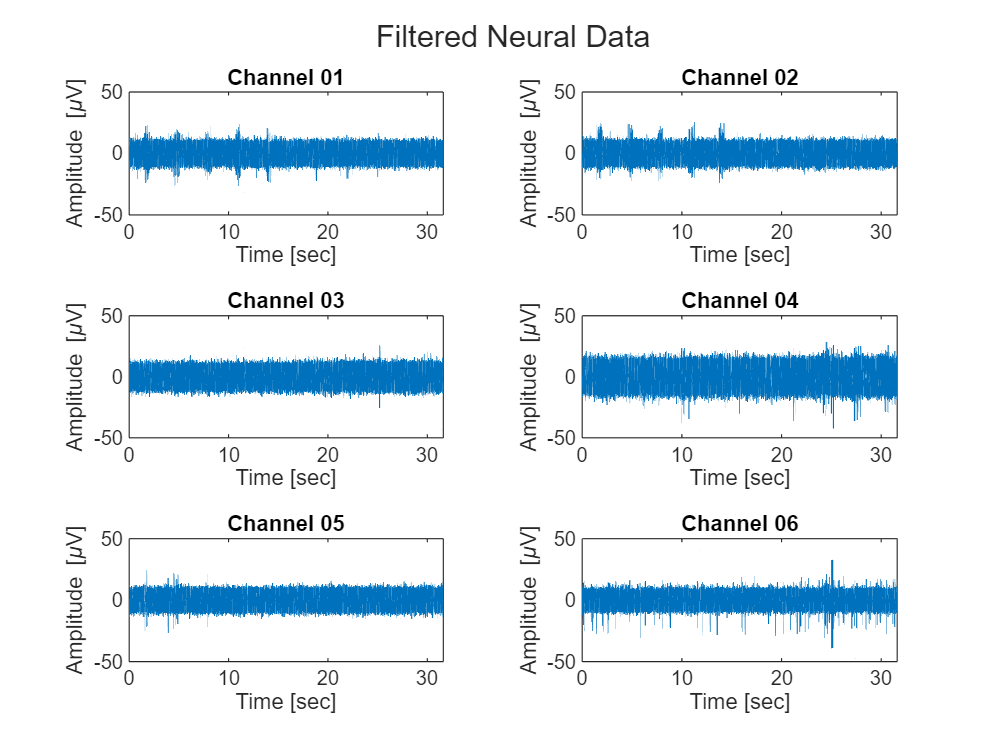

fig_2 = plot_filt_data(filt_neural_data, sample_rate);

## Procedure 2: Spike Detection

If your signal processing steps worked well, you should be able to detect some action action potentials.

### Step 1: Find the locations of the spikes (action potentials) for each channel

Your goal for this step is to provide the locations of spike occurrences in the `filt_neural_data` matrix.

You will start with the array `spike_locations`, which has the same shape as `filt_neural_data` and whose entries have been **initialized to zero**.

spike_locations = zeros(size(filt_neural_data))

spike_locations =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Then, modify the code below to replace `0`s with `1`s whenever you find a spike. We do this to leverage MATLAB's [logical indexing](https://blogs.mathworks.com/loren/2013/02/20/logical-indexing-multiple-conditions/) functionality down the line.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%spike_locations = (randi(7000, size(spike_locations)) == 1); % This code generates random spike locations. Replace with a spike detection algorithm
thresh = zeros(1,6);
%{
alpha = 0.4;
absfiltered = abs(filt_neural_data);
for i = 2:948199
    for j = 1:6
        filt_neural_data(i,j) = alpha*absfiltered(i,j) + (1-alpha)*filt_neural_data(i-1,j);
    end
end
%}
for i = 1:6
    thresh(1,i) = 4.5*rms(filt_neural_data(:,i));
end
thresh(1,6) = thresh(1,6)+2;
for i = 1:6
    spike_locations(:,i) = filt_neural_data(:,i) > thresh(1,i);
    spike_locations(:,i) = double(spike_locations(:,i));
end
filt_neural_data = double(filt_neural_data);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Step 2: Visualize the spike locations as spike trains in a raster plot

The raster plot below draws a vertical black line at each of the locations specified in `spike_locations`.

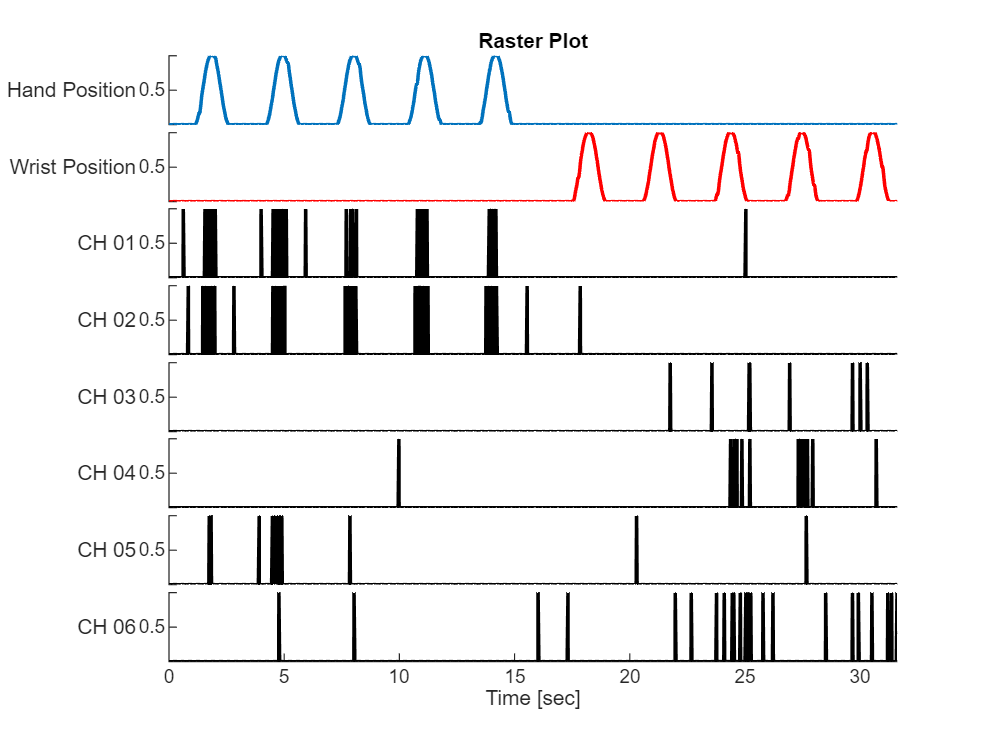

fig_3 = plot_spike_trains(spike_locations, training_data);

### Step 3: Plot the action potential waveforms using the spike locations

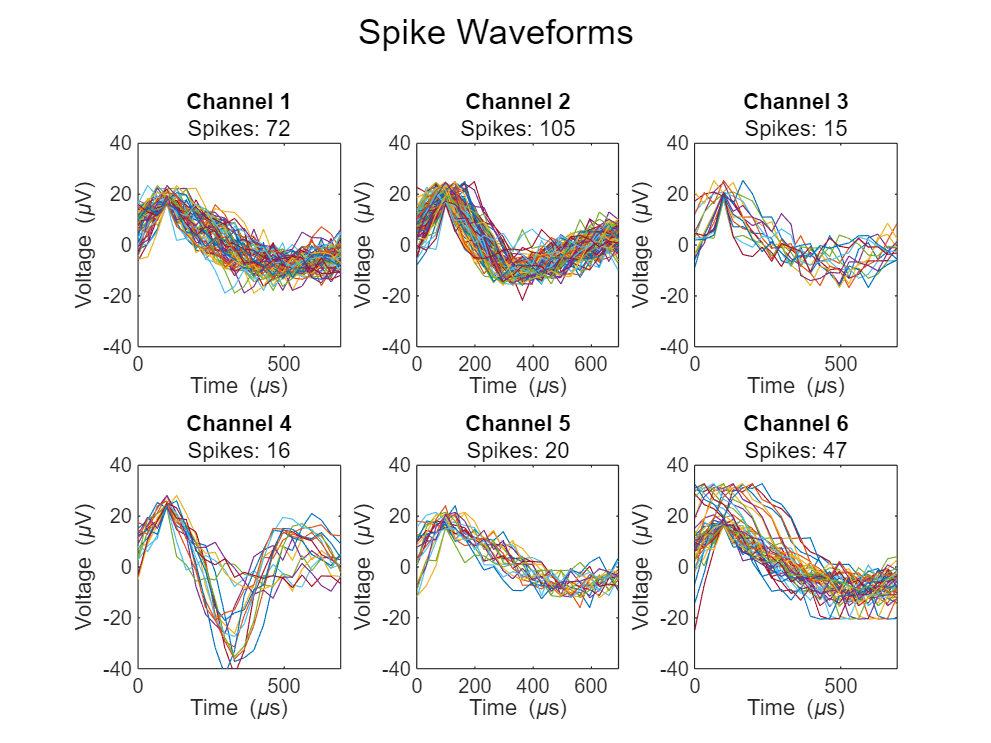

spike_waveforms = get_action_potentials(spike_locations, filt_neural_data, 'Spike Waveforms');

### Step 4: Calculate the SNR of each detected spike

First, let's explore how we have stored the waveforms associated with each spike. 

`spike_waveforms` is a [MATLAB cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) that has one row per channel.

spike_waveforms

spike_waveforms = 6×1 cell array
    {1×72  cell}
    {1×105 cell}
    {1×15  cell}
    {1×16  cell}
    {1×20  cell}
    {1×47  cell}


Each of these rows is also a cell array containing a variable number of waveforms based on the information in `spike_locations`. 

spike_waveforms{:}

ans = 1×72 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1

ans = 1×105 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×

ans = 1×15 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


ans = 1×16 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


ans = 1×20 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


ans = 1×47 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


To access the waveforms, you need to specify the channel you want and the waveform you are interested in. 

chan_idx = 1; % random channel
waveform_idx = 7; % random waveform

The waveform itself is a vector containing `22` samples of neural data, which is equivalent to `0.1 ms` before and `0.6 ms `after the spike detection event.

waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data =     8.9015
   11.2778
   14.8077
   15.9213
   14.6308
   11.3069
   10.0118
    7.4088
    6.4763
    7.6594


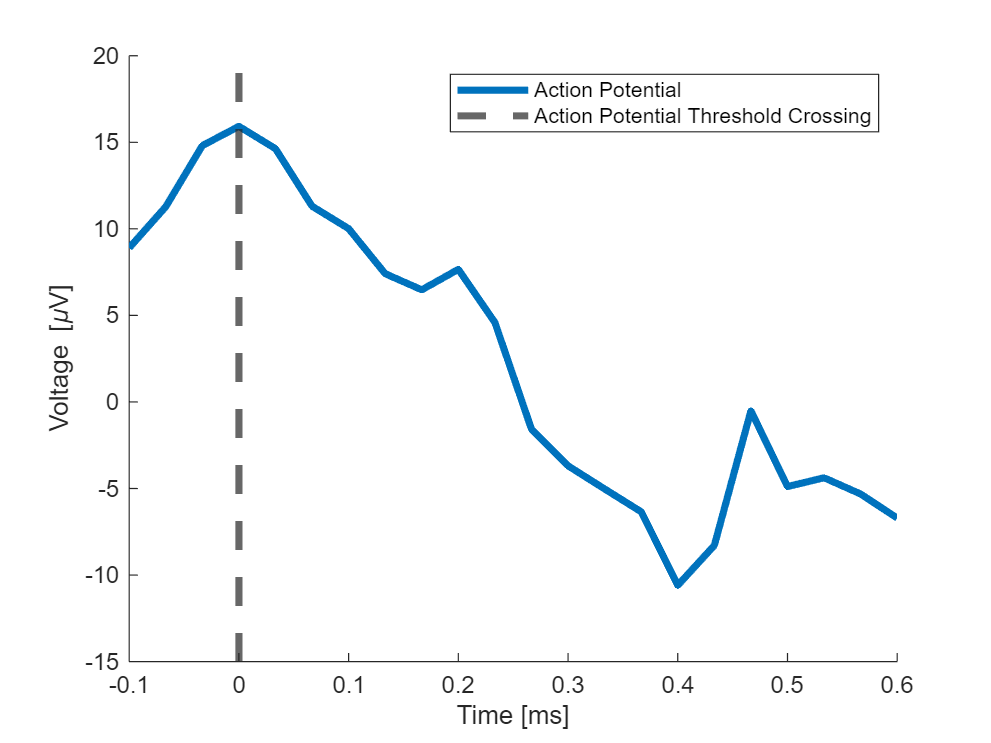

figure
waveform_time = (-3:1:18)'/training_data.sample_rate*1e3;
plot(waveform_time, waveform_data, LineWidth=3)
xline(0, LineWidth=3, LineStyle="--")
xlabel("Time [ms]")
ylabel("Voltage [\muV]")
legend(["Action Potential", "Action Potential Threshold Crossing"])
box off

Now, consider the image below, which shows action potentials as a function of distance to a neuron. Which action potential has the best SNR in the image below? Which channel of data provides the best SNR? Where might each channel be in relation to a given neuron? Are any channels recording from multiple neurons? 

One of your requirements for this research project is to determine if there are any statistical differences in the SNR among the electrodes.

For more context about the image below, read the document titled *"Introduction to Neural Recordings"* under the Neural Recordings Reading Assignment on Canvas. 

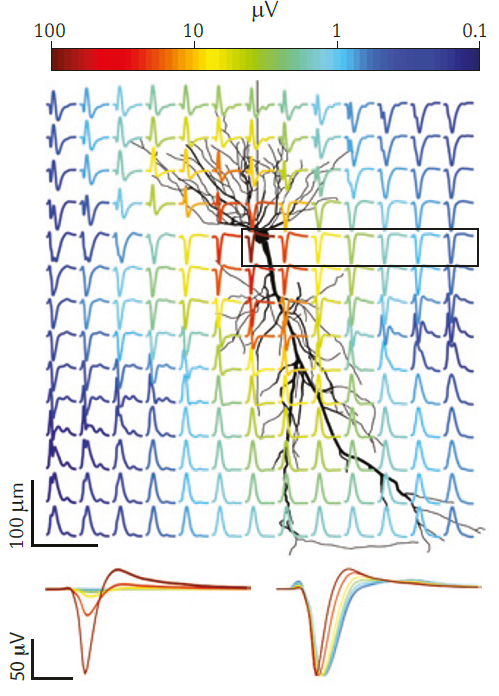

Calculate the SNR of each waveform in `spike_waveforms`. Use the following code to access each waveform:

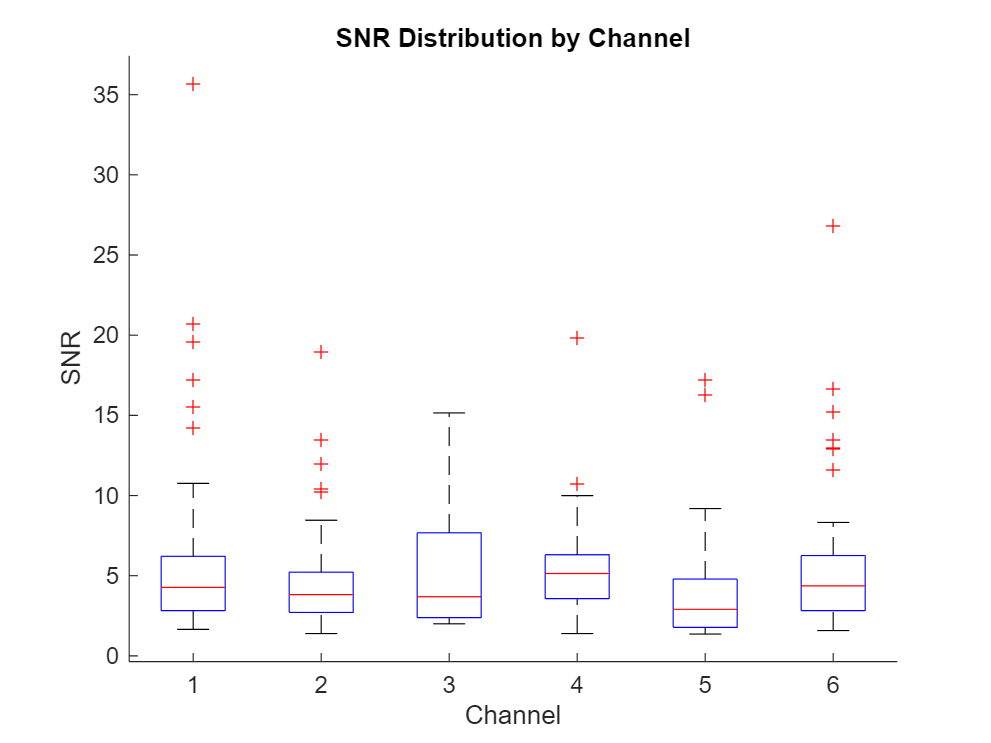

snr_values = cell(1, 6);

for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    chan_snr = zeros(1, length(chan_waveforms));

    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};

        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%
        % "Signal" = peak-to-peak amplitude of the spike waveform
        signal_amplitude = max(waveform_data) - min(waveform_data);

        % "Noise" = std of the pre-threshold-crossing baseline samples
        % (samples 1:3 correspond to the -3 to 0 index window, or before
        % the spike detection event)
        noise_std = std(waveform_data(1:3));

        % SNR definition
        % SNR = peak-to-peak signal / (2 * noise std)
        chan_snr(waveform_idx) = signal_amplitude / (2 * noise_std);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end

    snr_values{chan_idx} = chan_snr;
end

% --- Plot the SNR distributions ---
figure
boxplot_data = [];
boxplot_groups = [];
for chan_idx = 1:6
    boxplot_data = [boxplot_data, snr_values{chan_idx}];
    boxplot_groups = [boxplot_groups, chan_idx*ones(1, length(snr_values{chan_idx}))];
end
boxplot(boxplot_data, boxplot_groups)
xlabel('Channel')
ylabel('SNR')
title('SNR Distribution by Channel')
box off


% Run stats: is there a difference across channels?
[p, tbl, stats] = kruskalwallis(boxplot_data, boxplot_groups, 'off');
fprintf('Kruskal-Wallis p-value across channels: %.4g\n', p);

Kruskal-Wallis p-value across channels: 0.1249



% If significant, follow up with pairwise comparisons
if p < 0.05
    figure
    multcompare(stats);
    title('Pairwise Channel Comparisons (SNR)')
end


After you've calculated SNRs you should have 6 distributions total (1 for each channel). Make sure to **plot the SNR values** and **run stats**! 

## Procedure 3: Feature Extraction

### Step 1: Implement your feature extraction algorithm

The only requirement for generating features is that the length of your `neural_features` must match the size of the kinematics. The reason for this is that the kinematics are acting as labels for your features. For more information about this requirement, check notebook 03 on training the neural network.

If the lengths don't match as a result of your calculations, you can [pad the array with zeros](https://www.mathworks.com/help/images/ref/padarray.html).

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Feature extraction variable definitions
n_kinematic_samples = length(training_data.hand_kinematics);
n_neural_samples = size(spike_locations, 1);
n_chans = size(spike_locations, 2);


% Feature Extraction Method 1: Binning

% Bin spike counts per channel into windows that match the number of
% kinematic samples

bin_size = floor(n_neural_samples / n_kinematic_samples);

neural_features_binned = zeros(n_kinematic_samples, n_chans);

for chan_idx = 1:n_chans
    for bin_idx = 1:n_kinematic_samples
        idx_start = (bin_idx - 1)*bin_size + 1;
        idx_end = min(idx_start + bin_size - 1, n_neural_samples);
        % Spike count in this bin = firing rate proxy for this channel
        neural_features_binned(bin_idx, chan_idx) = sum(spike_locations(idx_start:idx_end, chan_idx));
    end
end

assert(length(neural_features_binned) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
neural_features_binned = normalize(neural_features_binned, "range", [0 1]);
plot_features(training_data, neural_features_binned);


% Feature Extraction Method 2: Simple Exponential Smoothing (SES)

% Smooths the signal based on alpha (the TAs mentioned that filters can be
% used as feature extraction methods)

alpha = 0.1

alpha = 0.1000

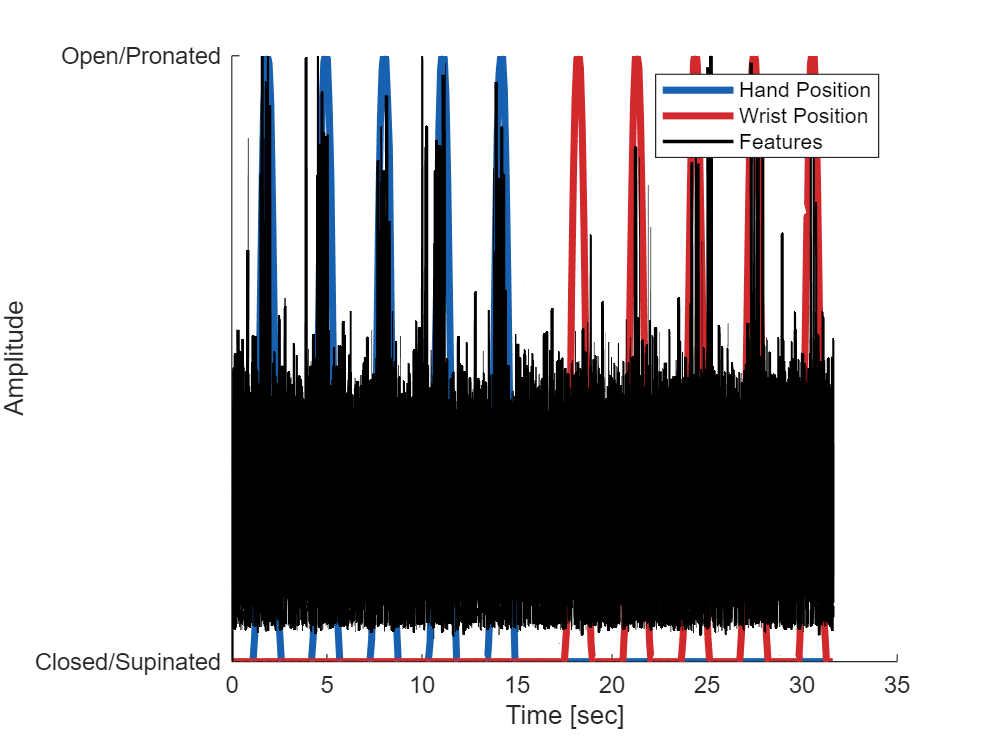

neural_features_SES = zeros(n_neural_samples, n_chans);
absfiltered = abs(filt_neural_data);
for i  = 2:n_neural_samples
    for j = 1:n_chans
        neural_features_SES(i,j) = alpha*absfiltered(i,j) + (1-alpha)*neural_features_SES(i-1,j);
    end
end

assert(length(neural_features_SES) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
neural_features_SES = normalize(neural_features_SES, "range", [0 1]);
plot_features(training_data, neural_features_SES);

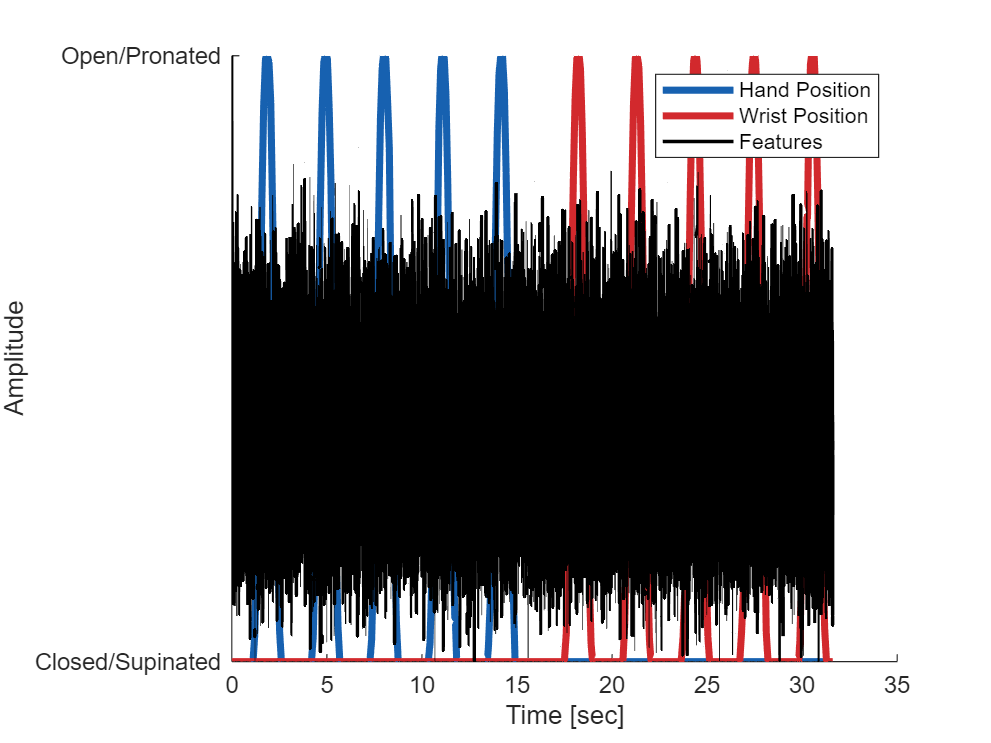



% Feature Extration Method 3: Mean - Centered Zero Crossings and Zero Crossing Rates

%Counts the amount of time the signal crosses zero over time using a
%sliding window and the rates

sig = zeros(n_neural_samples, n_chans);
neural_features_ZC = zeros(n_neural_samples, n_chans);
neural_features_ZCR = zeros(n_neural_samples, n_chans);
sigsum = zeros(n_neural_samples, n_chans);
trans = zeros(n_neural_samples, n_chans);
win_size = 300;
sig(1,:) = filt_neural_data(1,:) >= 0;
meansigsum = zeros(n_neural_samples,n_chans);
for j = 1:n_chans
    for i = 2:n_neural_samples
        if filt_neural_data(i,j) >0 || filt_neural_data(i,j) == 0
                sig(i,j) = 1;
        else
                sig(i,j) = 0;
        end
        trans(i,j) = abs(sig(i,j)-sig(i-1,j));
        if i > win_size
          sigsum(i,j) = sigsum(i-1,j) + trans(i,j) - trans(i-win_size,j);
          meansigsum(i,j) = meansigsum(i-1,j) + (sigsum(i,j) - sigsum(i-win_size,j))/win_size;
        else
          win_size_len = max(1, i-1);
          sigsum(i,j) = sigsum(i-1,j) + trans(i,j) - trans(i-win_size_len,j);
          meansigsum(i,j) = mean(sigsum(1:i,j));
        end
        neural_features_ZC(i,j) = sigsum(i,j)-meansigsum(i,j);
        neural_features_ZCR(i,j) = neural_features_ZC(i,j)/win_size_len;
    end
end


assert(length(neural_features_ZC) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
neural_features_ZC = normalize(neural_features_ZC, "range", [0 1]);
plot_features(training_data, neural_features_ZC);

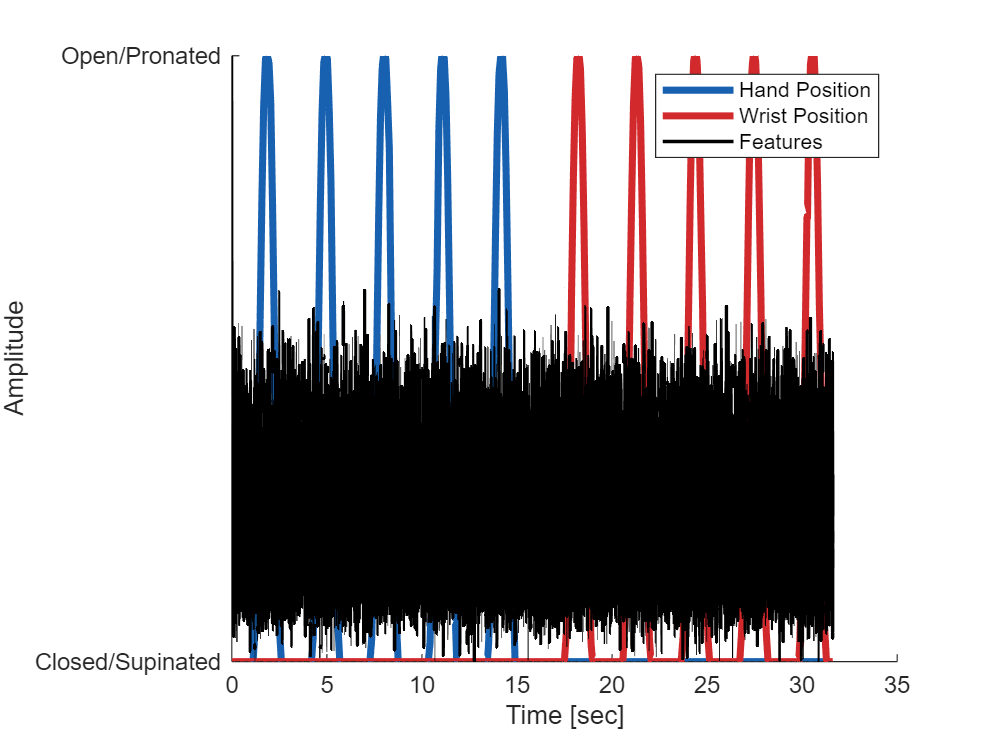


assert(length(neural_features_ZCR) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
neural_features_ZCR= normalize(neural_features_ZCR, "range", [0 1]);
plot_features(training_data, neural_features_ZCR);

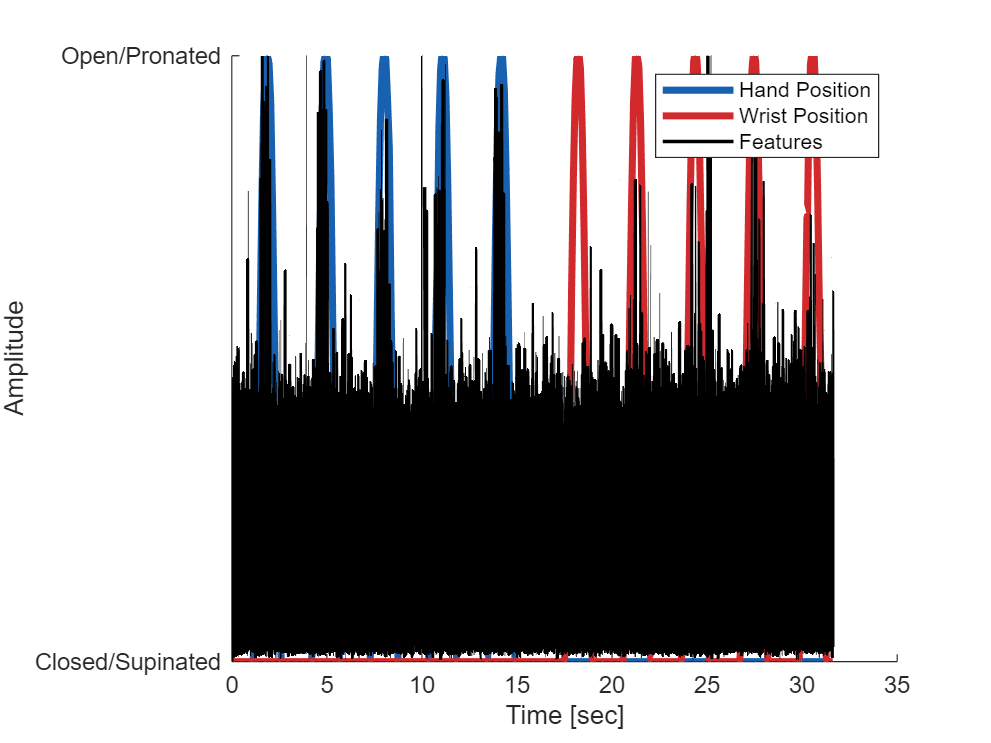


% Feature Extraction Method 5: Sliding Root Mean Square Window
%neural_features_RMS = sqrt(movmean(filt_neural_data.^2, win_size));
rms_win_size = 5;
neural_features_RMS = zeros(n_neural_samples, n_chans);
sq = filt_neural_data.^2;
sumsq = zeros(n_neural_samples, n_chans);
sumsq(1,:) = sq(1,:);

for i = 2:n_neural_samples
    if i > rms_win_size
        sumsq(i,:) = sumsq(i-1,:) + sq(i,:) - sq(i-rms_win_size,:);
    else
        sumsq(i,:) = sumsq(i-1,:) + sq(i,:);
    end
    win_len = min(i, rms_win_size);
    neural_features_RMS(i,:) = sqrt(sumsq(i,:)/win_len);
end


assert(length(neural_features_RMS) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
neural_features_RMS= normalize(neural_features_RMS, "range", [0 1]);
plot_features(training_data, neural_features_RMS);



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%save("results\features", "neural_features") %The original line for saving

% neural_features = neural_features_binned;
% save("results\features_binned", "neural_features")
% 
% neural_features = neural_features_SES;
% save("results\features_SES", "neural_features")
% 
% neural_features = neural_features_ZC;
% save("results\features_ZC", "neural_features")
% 
% neural_features = neural_features_ZCR;
% save("results\features_ZCR", "neural_features")
% 
% neural_features = neural_features_RMS;
% save("results\features_RMS", "neural_features")

save("results\features_binned", "neural_features_binned");
save("results\features_SES", "neural_features_SES");
save("results\features_ZC", "neural_features_ZC");
save("results\features_ZCR", "neural_features_ZCR");
save("results\features_RMS", "neural_features_RMS");

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. You do not need to change or understand the code below, but you are welcome to do so if it helps with your project.

function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.Color = "black";
raster_handle.LineProperties(1).Color = "#0072BD";
raster_handle.LineProperties(2).Color = "red";
raster_handle.DisplayLabels = ["Hand Position", "Wrist Position", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan)])
    subtitle(['Spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end

function fig_handle = plot_features(training_data, neural_features)
fig_handle = figure;
hold on
t = (0:1:length(training_data.hand_kinematics)-1)/training_data.sample_rate;
plot(t, training_data.hand_kinematics(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(t, training_data.hand_kinematics(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(t, neural_features,'Color',"#000000" ,'LineWidth', 1.5)
hold off
box off
ylim([0 1])
yticks([0 1])
yticklabels({"Closed/Supinated", "Open/Pronated"})
xlabel("Time [sec]")
ylabel("Amplitude")
legend(["Hand Position", "Wrist Position", "Features"])
end